# Take Home Mid-Term Test Linear System

### Nama : Juhen Fashikha Wildan

### NIM    : 163221047

### Link Youtube: [https://youtu.be/rSBdvSblpmk?si=pdwQe1xJFvolrCYo](https://youtu.be/rSBdvSblpmk?si=pdwQe1xJFvolrCYo) 

### Problem 1 

#### Gunakan MATLAB untuk menggambarkan sinyal seperti pada gambar dibawah ini

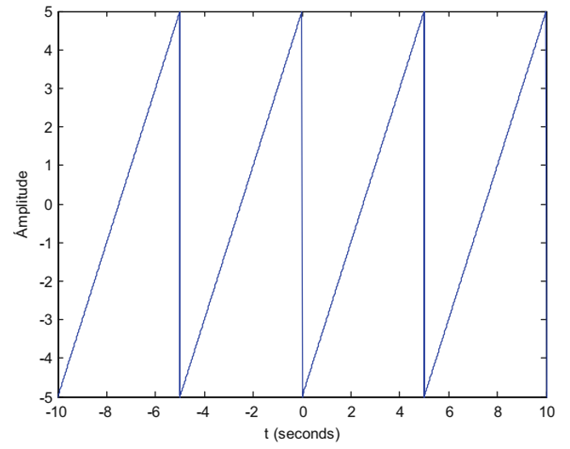

#### Solution:

% T = 1/f = (1/(1/5Hz) = 5 second; % periode
T = 4*(5); % Menghasilkan 4 periode gelombang sawtooth dengan frekuensi dasar 1/5 Hz.

fs = 1000; % sampling frequency
t = -10:1/fs:T-1/fs;

x = 5*sawtooth(2*pi*1/5*t); % sawtooth(2*pi*f*t), f = 1/5 Hz, T = 5 second

*note: x = sawtooth(t) menghasilkan gelombang gigi gergaji dengan periode 2 π untuk elemen susunan waktu t. sawtooth mirip dengan fungsi sinus tetapi menghasilkan gelombang gigi gergaji dengan puncak –1 dan 1. Gelombang gigi gergaji didefinisikan sebagai –1 pada kelipatan 2π dan meningkat secara linier terhadap waktu dengan kemiringan 1/π pada waktu lainnya.

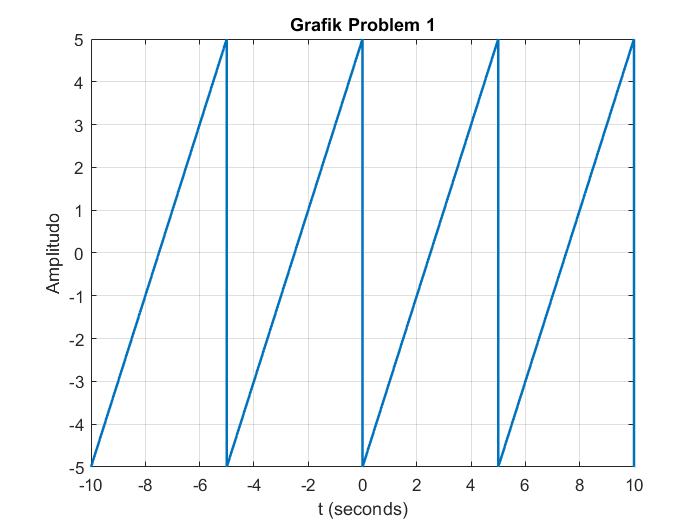

plot(t,x, "LineWidth", 1.5)
grid on
xlabel('t (seconds)')
ylabel('Amplitudo')
xlim([-10 10])
title('Grafik Problem 1')

### Problem 2

#### Gambarkan grafik sinyal berikut ini menggunakan MATLAB 

#### a) $x\left(t\right)=10\;\sin \left(2\pi t\right)\;\cos \left(\pi t-4\right),-10\le t\le 10$

#### b) $x\left(t\right)=2\;e^{-0,1t\;} \sin \left(2\pi t\right),-5\le t\le 5$

#### Solution (a):

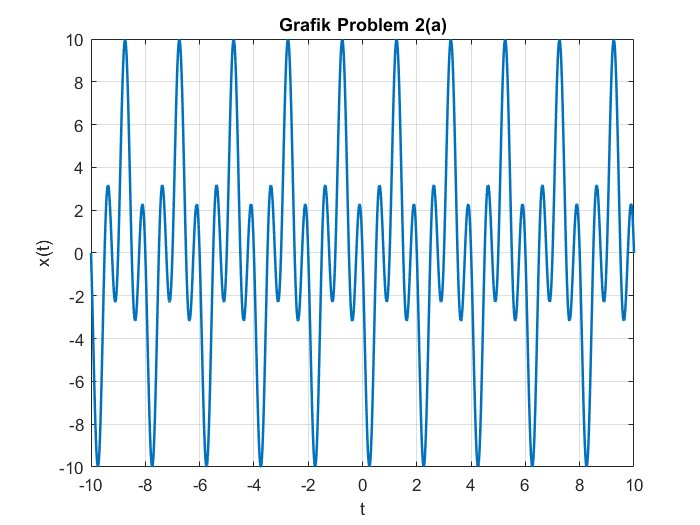

fs = 1000;
t = -10:1/fs:10;
x = 10*sin(2*pi*t).*cos(pi*t-4);

plot(t,x, "LineWidth",1.5)
grid on
ylabel('x(t)')
xlabel('t')
title('Grafik Problem 2(a)')

#### Solution (b):

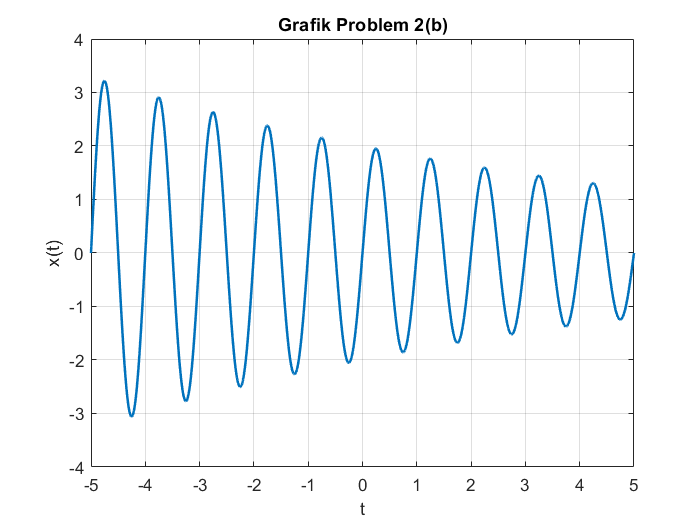

fs = 1000;
t = -5:1/fs:5;
x = 2*exp(-0.1*t).*sin(2*pi*t);

plot(t,x, "LineWidth",1.5)
grid on
ylabel('x(t)')
xlabel('t')
title('Grafik Problem 2(b)')

### Problem 3

#### Perhatikan sinyal dibawah ini, dan hitunglah menggunakan MATLAB $y\left(t\right)=x\left(t\right)*h\left(t\right)$.

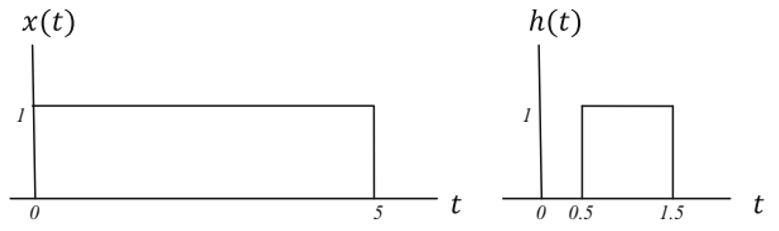

#### Solution:

Cara 1:

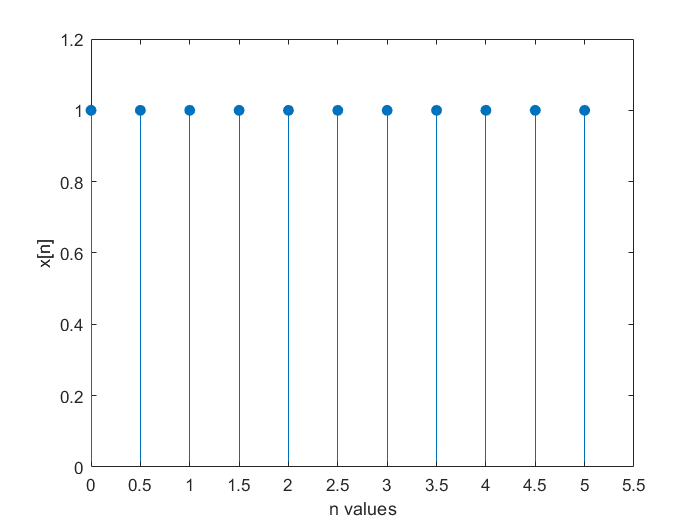

% diubah ke sinyal diskrit

% sinyal x[n]
n= 0:0.5:5;
x=[1,1,1,1,1,1,1,1,1,1,1];
stem(n,x,'filled')
xlabel('n values');
ylabel('x[n]');
ylim([0 1.2])
xlim([0 5.5])

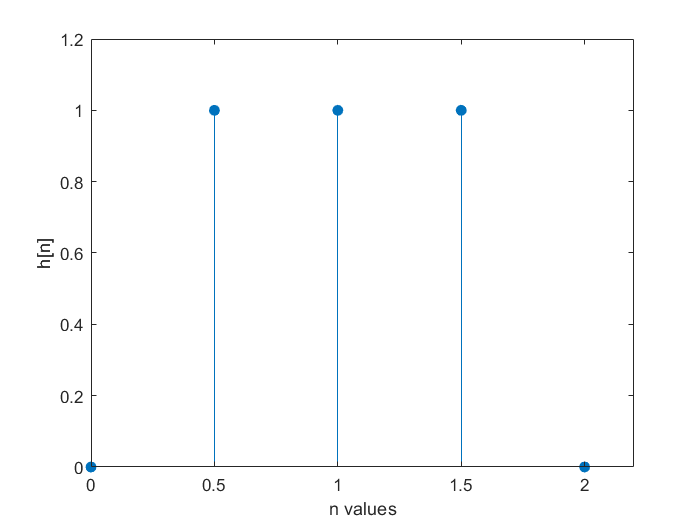

% sinyal h[n]
n= 0:0.5:2;
h=[0,1,1,1,0];
stem(n,h,'filled')
xlabel('n values');
ylabel('h[n]');
ylim([0 1.2])
xlim([0 2.2])

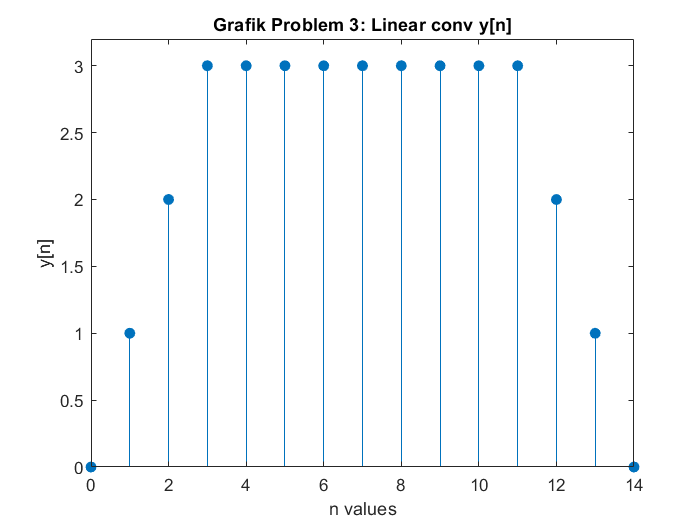

% sampling waktu x dan h harus sama, yakni 0.5

n = 0:14;
y = conv(x,h);
stem(n,y,'filled');
xlabel('n values');
ylabel('y[n]');
title('Grafik Problem 3: Linear conv y[n]');
ylim([0 3.2])

Cara 2:

[https://www.csun.edu/~skatz/ece350/matlab_tut_five.pdf](https://www.csun.edu/~skatz/ece350/matlab_tut_five.pdf) (referensi)

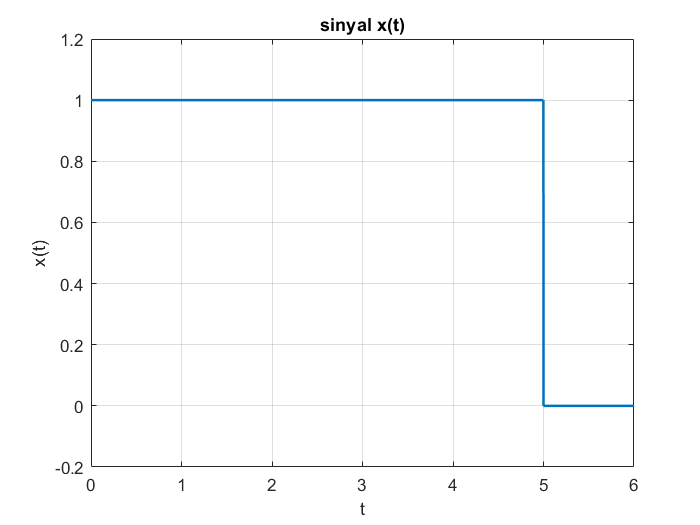

% sinyal x(t)

T = 0.001;

% Ingatlah bahwa kita menggunakan urutan waktu diskrit untuk memperkirakan fungsi waktu kontinu. 
% Jadi, semakin dekat nilai-nilainya, semakin baik perkiraan yang kita harapkan (lebih akurat).

t = 0:T:10;
x = (t>=0)-(t>=5);
plot(t,x,"LineWidth",1.5)
grid on
xlabel('t')
ylabel('x(t)')
ylim([-0.2 1.2])
xlim([0 6])
title('sinyal x(t)')

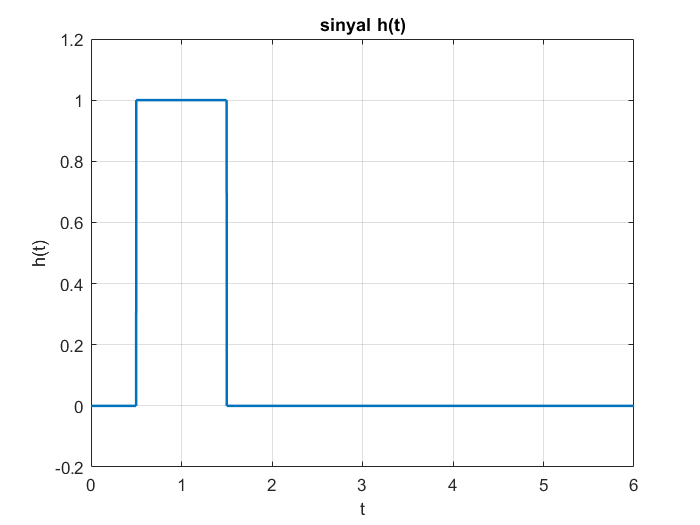

% sinyal h(t)

t = 0:T:10;
h = (t>=0.5)-(t>=1.5);
plot(t,h,"LineWidth",1.5)
grid on
xlabel('t')
ylabel('h(t)')
ylim([-0.2 1.2])
xlim([0 6])
title('sinyal h(t)')

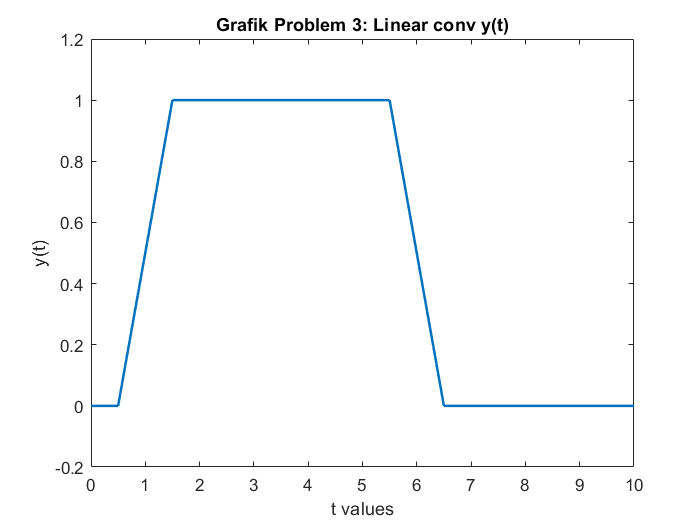

% Sinyal y(t) = x(t)*h(t)

t = 0:T:10;
y = T*conv(x,h);
plot(0:T:20,y,"LineWidth",1.5);
xlabel('t values');
ylabel('y(t)');
title('Grafik Problem 3: Linear conv y(t)');
ylim([-0.2 1.2])
xlim([0 10])

*note: Perhatikan di ruang kerja bahwa hasil konvolusi adalah barisan dengan panjang 20001. Secara umum, ketika kita menggabungkan dua barisan dengan panjang N1 dan N2, hasilnya adalah barisan dengan panjang N1 + N2 -1. Dalam problem ini, N1 = N2 = 10001. Jika kedua barisan tersebut berkisar pada interval t1 : T : t2 dan t3 : T : t4 , maka hasil konvolusinya akan berkisar pada t1 + t3 : T : t2 + t4 . Jadi, kita plot hasilnya menggunakan: >> plot(0:T:20,y)

### Problem 4

#### Suatu sistem mempunyai model matematika sebagai berikut

#### 
$$\frac{d^2 }{\mathrm{d}t^2 }y-2\frac{\mathrm{d}}{\mathrm{d}t}y+2y\left(t\right)=\cos \left(t\right)\;,y\left(0\right)=1,\overset{\bullet }{y} \left(0\right)=0$$


#### Dengan menggunakan MATLAB gambarkan grafik $y\left(t\right)=\;\ldotp \ldotp \ldotp \ldotp$, untuk $0\le t\le 6$.

#### Penyederhanaan model matematika:

#### 
$$\frac{d^2 }{\mathrm{d}t^2 }y=2\frac{\mathrm{d}}{\mathrm{d}t}y-2y\left(t\right)+\cos \left(t\right),y\left(0\right)=1,\overset{\bullet }{y} \left(0\right)=0$$


#### Solution:

% menggunakan 2nd order ODE
syms y(t)
Dy = diff(y);
ode = diff(y,t,2) == 2*diff(y,t)-2*y+cos(t)

$$ode(t) = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)=2\,\frac{\partial }{\partial t}y\left(t\right)+\cos\left(t\right)-2\,y\left(t\right)$$

cond1 = y(0) == 1;
cond2 = Dy(0) == 0;
conds = [cond1 cond2];
ySol(t) = dsolve(ode,conds)

$$ySol(t) = \frac{4\,{\mathrm{e}}^{t}\,\cos\left(t\right)}{5}-\frac{2\,{\mathrm{e}}^{t}\,\sin\left(t\right)}{5}+\cos\left(t\right)\,\left(\frac{\cos\left(2\,t\right)}{5}+\frac{\sin\left(2\,t\right)}{10}\right)-\sin\left(t\right)\,\left(\frac{\cos\left(2\,t\right)}{10}-\frac{\sin\left(2\,t\right)}{5}+\frac{1}{2}\right)$$

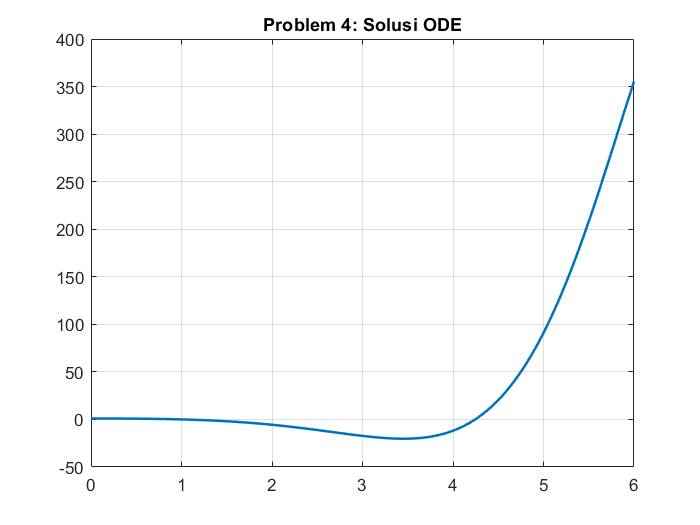

t = 0:0.01:6;
y = (4/5)*exp(t).*cos(t)-(2/5)*exp(t).*sin(t)+cos(t).*((1/5)*cos(2*t)+(1/10)*sin(2*t))-sin(t).*((1/10)*cos(2*t)-(1/5)*sin(2*t)+(1/2));
plot(t,y,'LineWidth',1.5)
grid on
title('Problem 4: Solusi ODE')

### Problem 5

#### Suatu Motor DC mempunyai model matematika dalam bentuk transfer function sebagai berikut

#### 
$$P\left(s\right)=\frac{\Omega \left(s\right)}{\;V\left(s\right)}=\frac{k_t }{\;\left(\textrm{Js}+b\right)\left(\textrm{Ls}+R\right)+k_t k_m }$$


#### dengan $v\left(t\right)$ adalah tegangan input motor dan $\omega \left(t\right)$ adalah kecepatan putar motor dalam $\frac{\textrm{rad}}{\sec }$. Jika $J=1,4*{10}^{-3} \;\textrm{kg}\ldotp m^2$, $L=0,18\;\textrm{mH}=0,18*{10}^{-3\;} H$, $R=2,6\;\Omega$, $b=0,015\;\frac{N\ldotp m}{\textrm{rad}/\sec }$, dan $v\left(t\right)=\left\lbrace \begin{array}{ll}
5V & ,\;t\ge 0\\
0V & ,\;\textrm{otherwise}
\end{array}\right.$, maka buatlah grafik $\omega \left(t\right)$ dengan menggunakan MATLAB. 

#### Solusi:

[http://www.engr.siu.edu/staff/spezia/Web438A/Lecture%20Notes/lesson14et438a.pdf](http://www.engr.siu.edu/staff/spezia/Web438A/Lecture%20Notes/lesson14et438a.pdf) (referensi)

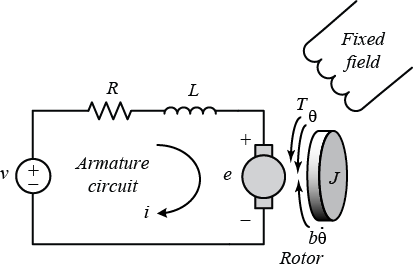

model matematika:

#### 
$$P\left(s\right)=\frac{\Omega \left(s\right)}{\;V\left(s\right)}=\frac{k_t }{\;\left(\textrm{Js}+b\right)\left(\textrm{Ls}+R\right)+k_t k_v }$$


#### 
$$P\left(s\right)=\frac{\Omega \left(s\right)}{\;V\left(s\right)}=\frac{k_t }{\;\textrm{JL}\ldotp s^2 +\left(\textrm{JR}+\textrm{bL}\right)\ldotp s+\left(\textrm{bR}+k_t k_v \right)}$$


Kondisi 1:

% Parameter Motor DC yang digunakan

J = 0.0014;% kg.m*2
b = 0.015;% N.m.s/rad
Kt = 0.01;% N.m/A
Kv = 0.01; % V/(rad/s)
R = 2.6; % Ohm
L = 0.00018; % Henry

P = tf(Kt,[J*L (J*R+b*L) (b*R+Kt*Kv)])

P =
 
                 0.01
  ----------------------------------
  2.52e-07 s^2 + 0.003643 s + 0.0391
 
Continuous-time transfer function.



#### 
$$v\left(t\right)=\left\lbrace \begin{array}{ll}
5V & ,\;t\ge 0\\
0V & ,\;\textrm{otherwise}
\end{array}\Longrightarrow V\left(s\right)=\frac{5}{s},\;t\ge 0\right.$$


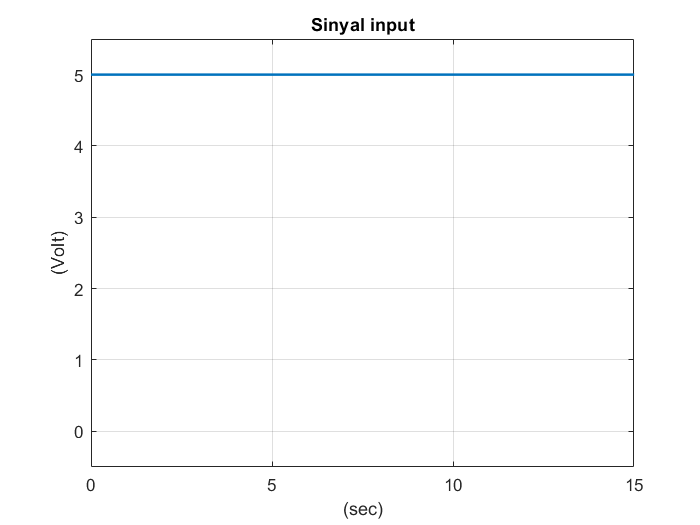

t = 0:0.001:100;
s1 = (t>=0);
v = 5*s1;
plot(t,v,"LineWidth",1.5)
grid on
xlabel('(sec)')
ylabel('(Volt)')
ylim([-0.5 5.5])
xlim([0 15])
title('Sinyal input')

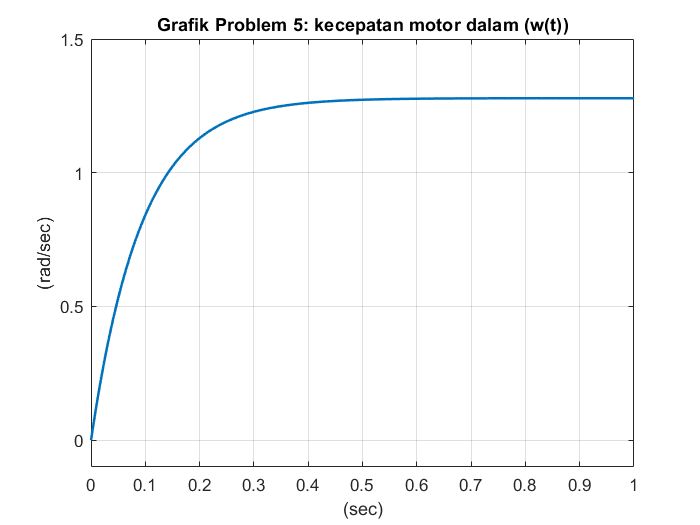

kec_putar = lsim(P,v,t);
plot(t,kec_putar,'LineWidth',1.5)
grid on
ylim([-0.1 1.5])
xlim([0 1])
xlabel('(sec)')
ylabel('(rad/sec)')
title('Grafik Problem 5: kecepatan motor dalam (w(t))')

Karena kecepatan putar dalam satuan $\frac{\textrm{rad}}{\sec }$ sulit dibayangkan maka diubah menjadi satuan rpm (root per minutes) dengan hubungan


$$1\;\frac{\textrm{rad}}{\sec }=9,5493\;\textrm{rpm}$$


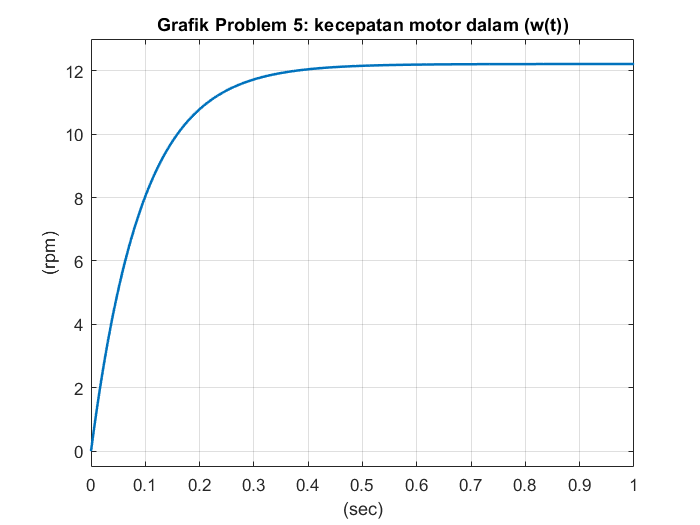

kec_putar = 9.5493*kec_putar;
plot(t,kec_putar,'LineWidth',1.5)
grid on
ylim([-0.5 13])
xlim([0 1])
xlabel('(sec)')
ylabel('(rpm)')
title('Grafik Problem 5: kecepatan motor dalam (w(t))')

Kondisi 2:

% Parameter Motor DC yang digunakan

J = 0.0014;% kg.m*2
b = 0.015;% N.m.s/rad
Kt = 0.042;% N.m/A
Kv = 0.042; % V/(rad/s)
R = 2.6; % Ohm
L = 0.00018; % Henry

P = tf(Kt,[J*L (J*R+b*L) (b*R+Kt*Kv)])

P =
 
                 0.042
  -----------------------------------
  2.52e-07 s^2 + 0.003643 s + 0.04076
 
Continuous-time transfer function.



#### 
$$v\left(t\right)=\left\lbrace \begin{array}{ll}
5V & ,\;t\ge 0\\
0V & ,\;\textrm{otherwise}
\end{array}\Longrightarrow V\left(s\right)=\frac{5}{s},\;t\ge 0\right.$$


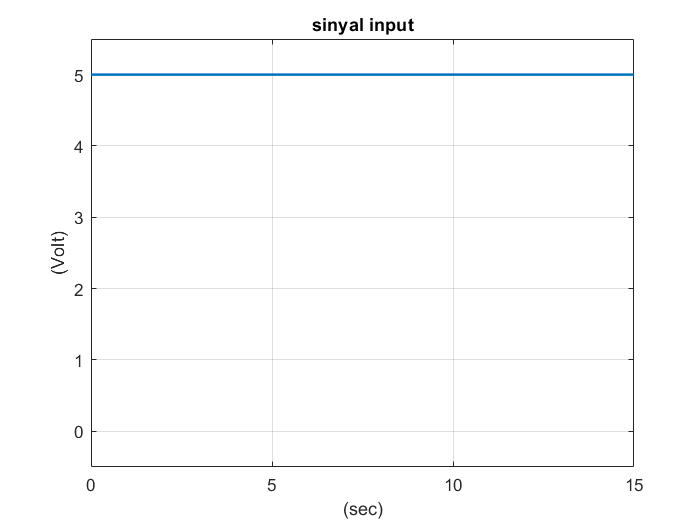

t = 0:0.001:100;
s1 = (t>=0);
v = 5*s1;
plot(t,v,"LineWidth",1.5)
grid on
xlabel('(sec)')
ylabel('(Volt)')
ylim([-0.5 5.5])
xlim([0 15])
title('sinyal input')

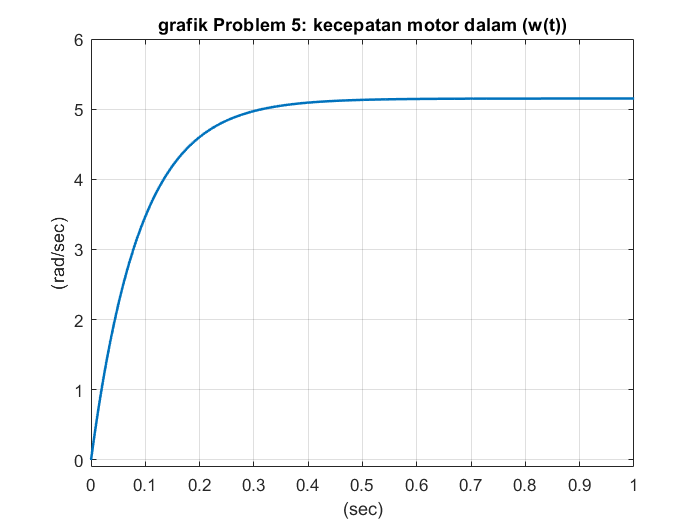

kec_putar = lsim(P,v,t);
plot(t,kec_putar,'LineWidth',1.5)
grid on
ylim([-0.1 6])
xlim([0 1])
xlabel('(sec)')
ylabel('(rad/sec)')
title('grafik Problem 5: kecepatan motor dalam (w(t))')

Karena kecepatan putar dalam satuan $\frac{\textrm{rad}}{\sec }$ sulit dibayangkan maka diubah menjadi satuan rpm (root per minutes) dengan hubungan


$$1\;\frac{\textrm{rad}}{\sec }=9,5493\;\textrm{rpm}$$


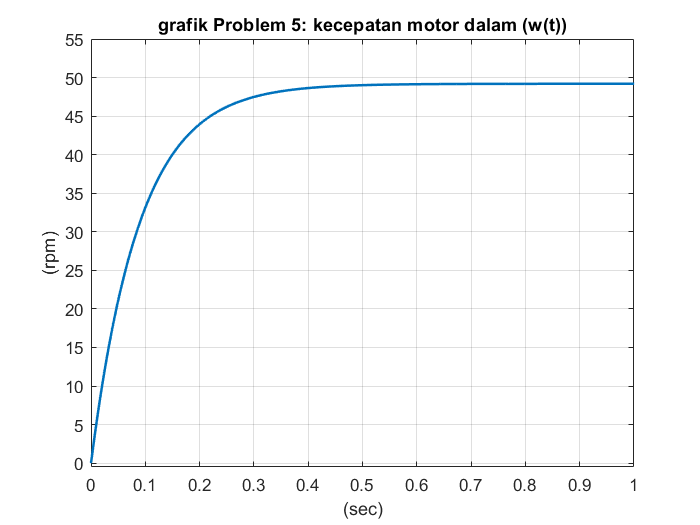

kec_putar = 9.5493*kec_putar;
plot(t,kec_putar,'LineWidth',1.5)
grid on
ylim([-0.5 55])
xlim([0 1])
xlabel('(sec)')
ylabel('(rpm)')
title('grafik Problem 5: kecepatan motor dalam (w(t))')

Kondisi 3:

[http://www.engr.siu.edu/staff/spezia/Web438A/Lecture%20Notes/lesson14et438a.pdf](http://www.engr.siu.edu/staff/spezia/Web438A/Lecture%20Notes/lesson14et438a.pdf) (referensi)

% Parameter Motor DC yang digunakan

J = 0.0014;% kg.m*2
b = 0.015;% N.m.s/rad
Kt = 0.06;% N.m/A
Kv = 0.06; % V/(rad/s)
R = 2.6; % Ohm
L = 0.00018; % Henry

P = tf(Kt,[J*L (J*R+b*L) (b*R+Kt*Kv)])

P =
 
                 0.06
  ----------------------------------
  2.52e-07 s^2 + 0.003643 s + 0.0426
 
Continuous-time transfer function.



#### 
$$v\left(t\right)=\left\lbrace \begin{array}{ll}
5V & ,\;t\ge 0\\
0V & ,\;\textrm{otherwise}
\end{array}\Longrightarrow V\left(s\right)=\frac{5}{s},\;t\ge 0\right.$$


t = 0:0.001:100;
s1 = (t>=0);
v = 5*s1;
plot(t,v,"LineWidth",1.5)
grid on
xlabel('(sec)')
ylabel('(Volt)')
ylim([-0.5 5.5])
xlim([0 15])
title('sinyal input')

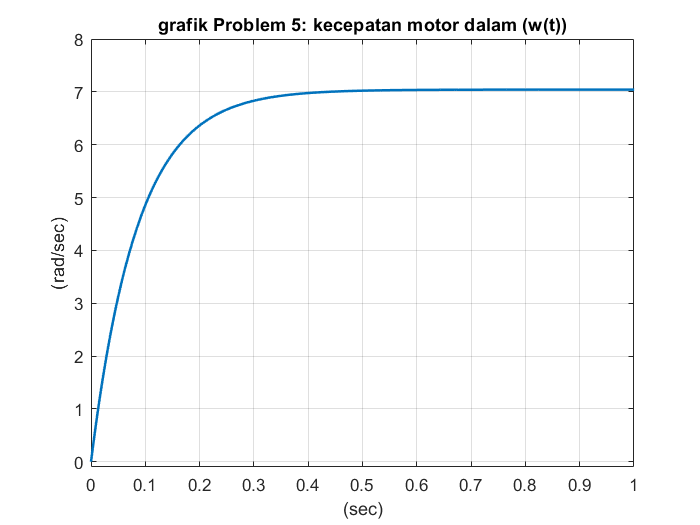

kec_putar = lsim(P,v,t);
plot(t,kec_putar,'LineWidth',1.5)
grid on
ylim([-0.1 8])
xlim([0 1])
xlabel('(sec)')
ylabel('(rad/sec)')
title('grafik Problem 5: kecepatan motor dalam (w(t))')

Karena kecepatan putar dalam satuan $\frac{\textrm{rad}}{\sec }$ sulit dibayangkan maka diubah menjadi satuan rpm (root per minutes) dengan hubungan


$$1\;\frac{\textrm{rad}}{\sec }=9,5493\;\textrm{rpm}$$


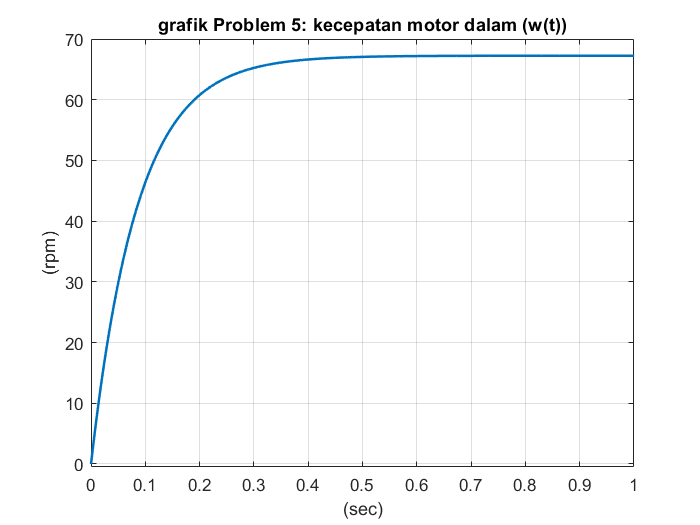

kec_putar = 9.5493*kec_putar;
plot(t,kec_putar,'LineWidth',1.5)
grid on
ylim([-0.5 70])
xlim([0 1])
xlabel('(sec)')
ylabel('(rpm)')
title('grafik Problem 5: kecepatan motor dalam (w(t))')

Kondisi 4:

[https://www.mathworks.com/help/control/ug/dc-motor-control.html](https://www.mathworks.com/help/control/ug/dc-motor-control.html) (referensi kt dan kv)

% Parameter Motor DC yang digunakan

J = 0.0014;% kg.m*2
b = 0.015;% N.m.s/rad
Kt = 0.1;% N.m/A
Kv = 0.1; % V/(rad/s)
R = 2.6; % Ohm
L = 0.00018; % Henry

P = tf(Kt,[J*L (J*R+b*L) (b*R+Kt*Kv)])

P =
 
                 0.1
  ---------------------------------
  2.52e-07 s^2 + 0.003643 s + 0.049
 
Continuous-time transfer function.



#### 
$$v\left(t\right)=\left\lbrace \begin{array}{ll}
5V & ,\;t\ge 0\\
0V & ,\;\textrm{otherwise}
\end{array}\Longrightarrow V\left(s\right)=\frac{5}{s},\;t\ge 0\right.$$


t = 0:0.001:100;
s1 = (t>=0);
v = 5*s1;
plot(t,v,"LineWidth",1.5)
grid on
xlabel('(sec)')
ylabel('(Volt)')
ylim([-0.5 5.5])
xlim([0 15])
title('sinyal input')

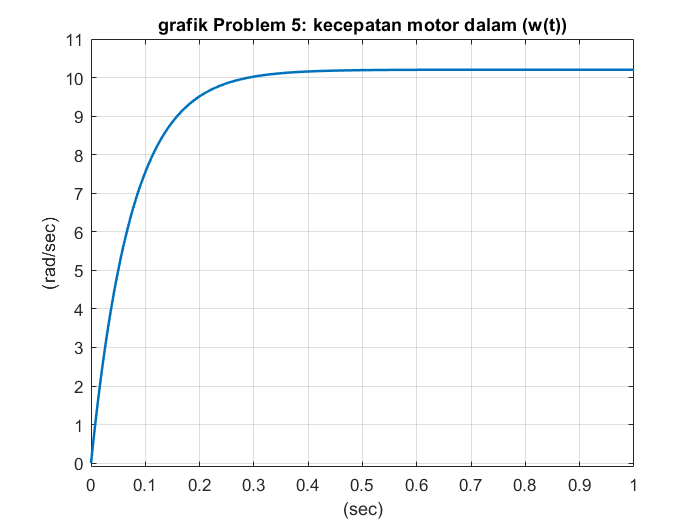

kec_putar = lsim(P,v,t);
plot(t,kec_putar,'LineWidth',1.5)
grid on
ylim([-0.1 11])
xlim([0 1])
xlabel('(sec)')
ylabel('(rad/sec)')
title('grafik Problem 5: kecepatan motor dalam (w(t))')

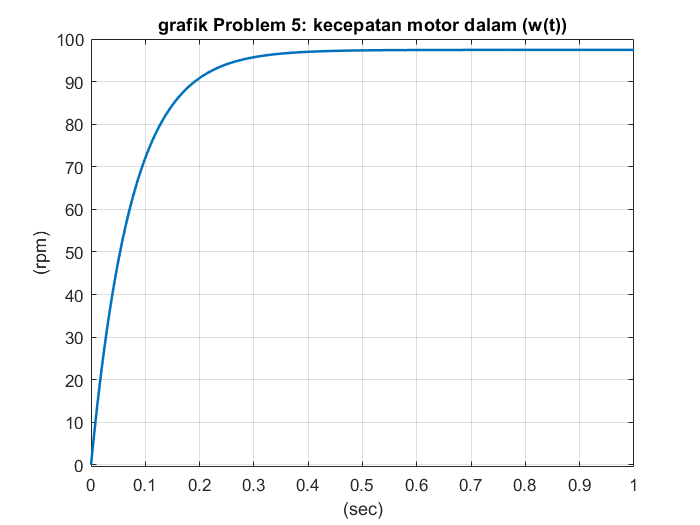

kec_putar = 9.5493*kec_putar;
plot(t,kec_putar,'LineWidth',1.5)
grid on
ylim([-0.5 100])
xlim([0 1])
xlabel('(sec)')
ylabel('(rpm)')
title('grafik Problem 5: kecepatan motor dalam (w(t))')